# Create a Scatter Plot

`scatter` creates a scatter plot with circular markers at the locations specified by the input vectors $x$ and $y$

### Create Data to Plot

 Create a vector$x$ of values between $\left\lbrack 0,10\right\rbrack$, and define $y$ equated to $x$ with random noise applied.

x = linspace(0,10,75);
y = x + (rand(size(x)) - 0.5) * 5;

### Basic Scatter Plot

Create a scatter plot of $x$ and $y$ with default circle points.

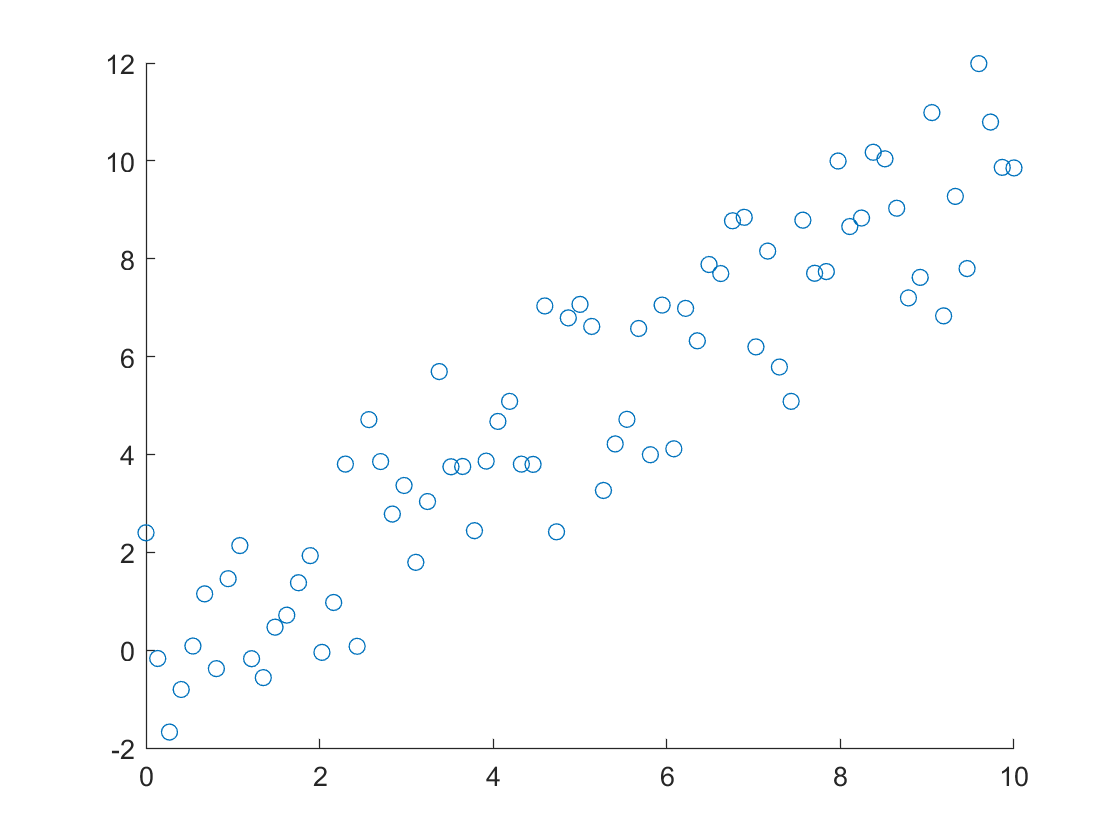

scatter(x,y)

## Customizations

### Vary Circle Size and Fill

Define a corresponding vector that defines the size of each $x-y$ point. Specify scatter point options to use filled circles.

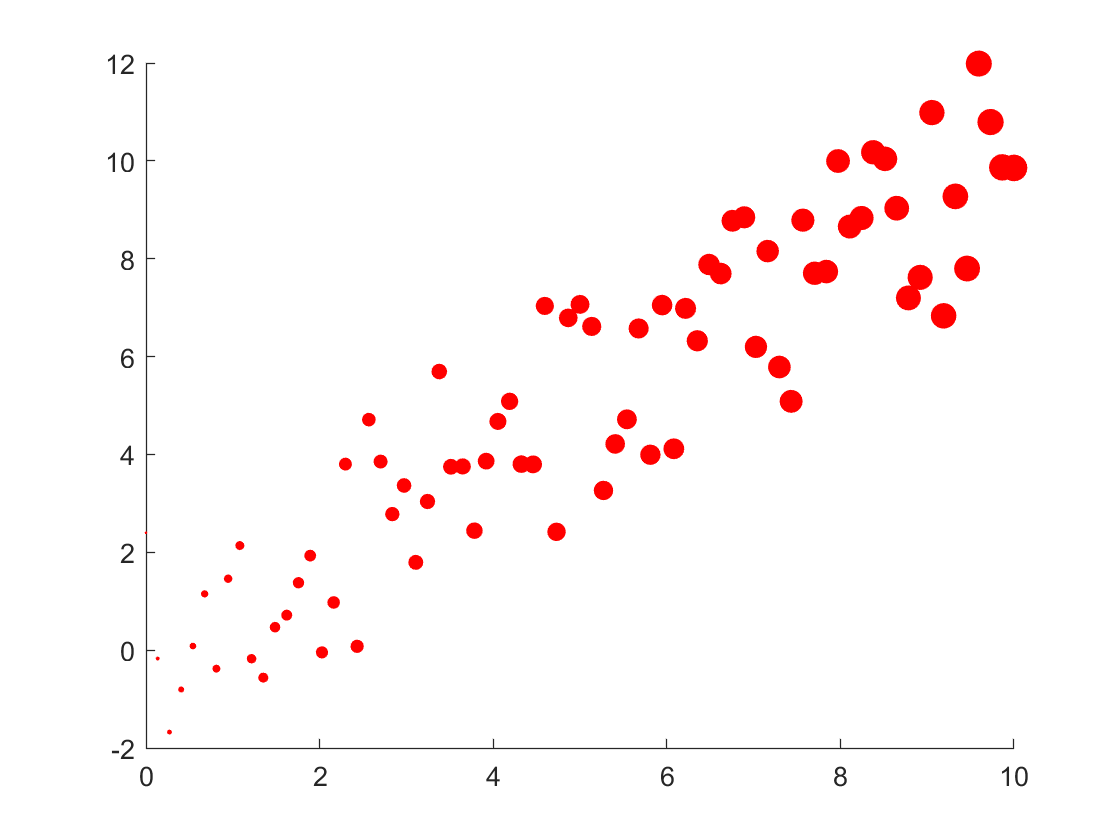

sz = linspace(1,100,length(x));
PointColor = 'r';
scatter(x, y,...
    sz,...                          % Specify the size input
    PointColor,...                  % Specify the marker color input
    "filled")                       % Select the filled point appearance

### Create Color Patterns

Define a color pattern the same dimension as the data. Create a vector that sorts the data points by their distance from the line $y=x$. Arrange the colormap vector so that the edges of the color vector correspond to the points closest and furthest from the line$y=x$, additionally, specify the shading characteristics to taper off in a similar fashion using the `AlphaData` field. Create a scatter plot with the custom color pattern

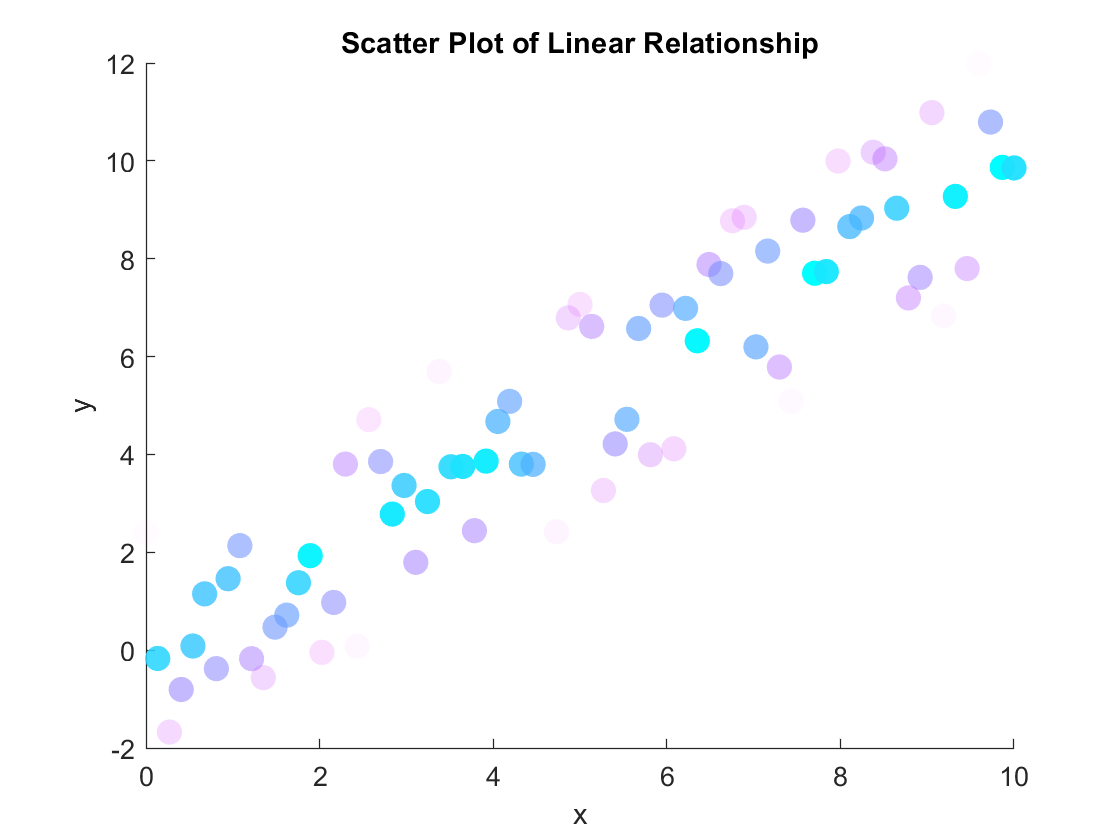

colorVector = cool(numel(x));
distFromXY = abs(y - x);
[ySort, sortIdx] = sort(distFromXY);
colorVector(sortIdx,:) = colorVector;
figure
s = scatter(x,y,90,colorVector,...
    "filled",...
    'o',...
    "AlphaData", (max(distFromXY) - distFromXY),...   % Set opacity for each point
    "MarkerFaceAlpha","flat");                        % Set the face alpha to flat

title("Scatter Plot of Linear Relationship")
xlabel('x')
ylabel('y')

## Additional Information

### Get All Scatter Properties

Graphics objects in MATLAB have many properties. To see all the properties of a scatter, uncomment the following code

% get(s)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[scatter](https://www.mathworks.com/help/matlab/ref/scatter.html)